% Step 1
x = imread('AxonExample.png');

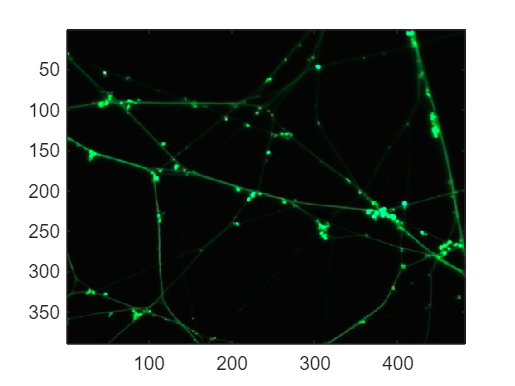

% Step 2
imagesc(x)

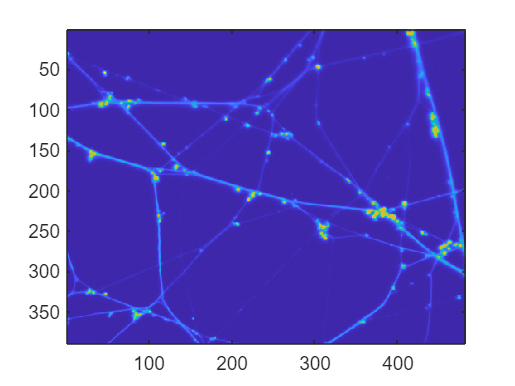

% Step 3 Convert to Grayscale and Display
xgray = (rgb2gray(x));
imagesc(xgray)

% Step 4 Threshold and make a binary image and display
T = 0.6

T = 0.6000

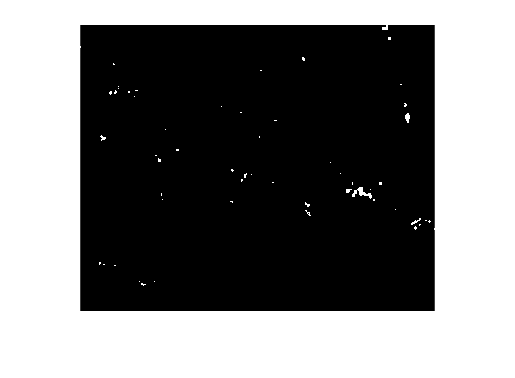

xthresh = imbinarize(xgray, T); imshow(xthresh);

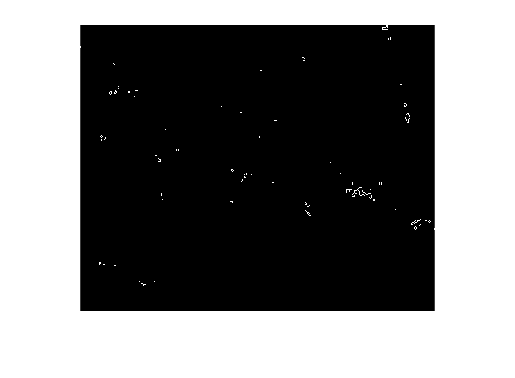

% Step 5
%Can you find and count the blebs using binary morphology? Note: blebs are the little 
%buds coming off the axons (almost circular blobs). Include:

% Step 5a) a connected-components style image of the identified blebs, 
% in which each bleb's pixels are given a single number 
% (bleb 1 = all 1 pixels, bleb 2 = all 2 pixels, etc.) 
% Step 5b) a grayscale image of just the blebs, 
% Step 5c) a count of the blebs
BW = bwmorph(xthresh, 'remove');
figure, imshow(BW)

CC = bwconncomp(BW)

CC = struct with fields:
    Connectivity: 8
       ImageSize: [389 482]
      NumObjects: 62
    PixelIdxList: {1×62 cell}


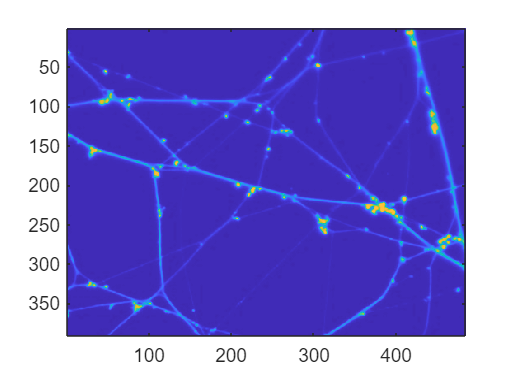

% Step 6
% Convolve the grayscale image with a filter of your choosing. 
h = fspecial('gaussian');
C = conv2(xgray, h);
imagesc(C)

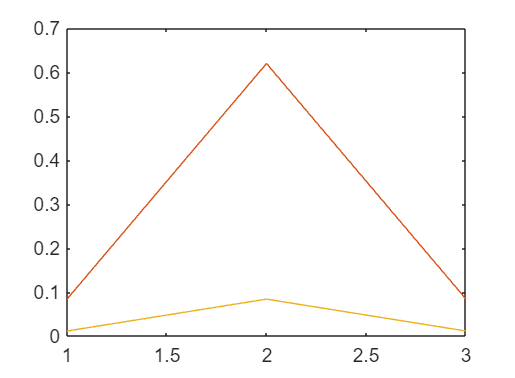

% Plot the filter kernel and your output image in your report.
plot(h)


% Explain the connection between the filter kernel 
% structure and the change in the binary image.
% (see PDF report)